% Settings
clear;

## Numerical Example

### Vehicle Model

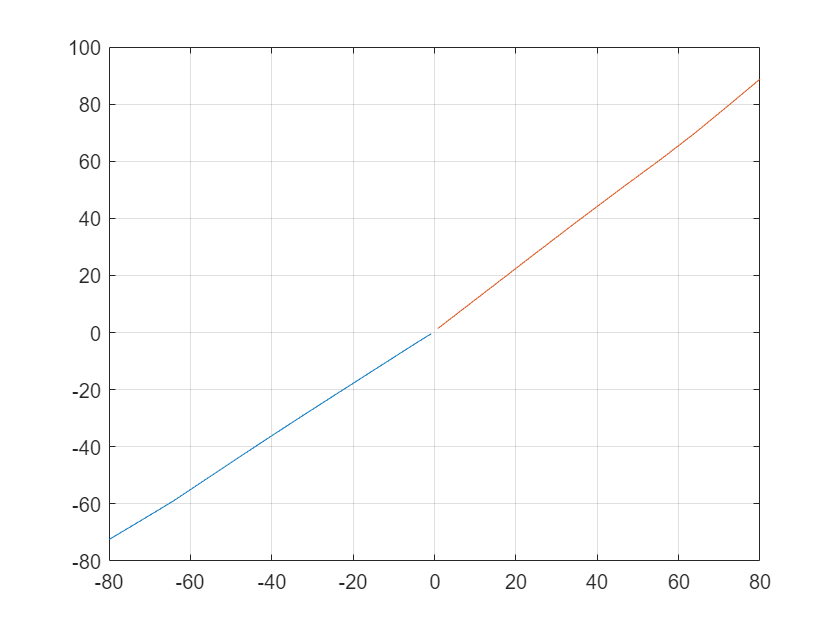

e = [0.01 58.72 56.62
0.02 72.24 70.63
0.05 83.89 83.02
0.1 88.67 88.20
0.2 91.28 91.04
0.3 92.12 91.98
0.4 92.71 92.56
0.5 93.31 93.14
0.6 93.91 93.71
0.7 94.51 94.29
0.8 94.43 94.74
0.9 93.67 94.07
1 92.91 93.41];
P_eff = 0.97;
P_max = 80;
P_elec = [-e(:,1)*P_max.*e(:,3).*0.01.*P_eff e(:,1)*P_max./(e(:,2)*0.01.*P_eff)];
P_mech = [-e(:,1)*P_max e(:,1)*P_max];
plot(P_mech,P_elec);
grid;


P_elec = P_elec(:);
P_mech = P_mech(:);
t = table(P_elec,P_mech);
mdl=fitlm(t,"P_elec~P_mech^2")

mdl = Linear regression model:
    P_elec ~ 1 + P_mech + P_mech^2

Estimated Coefficients:
                   Estimate         SE        tStat      pValue  
                   _________    __________    ______    _________

    (Intercept)       1.4092       0.17101    8.2406     2.57e-08
    P_mech            1.0057     0.0029099    345.61    3.075e-44
    P_mech^2       0.0010903    6.0529e-05    18.013    4.672e-15


Number of observations: 26, Error degrees of freedom: 23
Root Mean Squared Error: 0.646
R-squared: 1,  Adjusted R-Squared: 1
F-statistic vs. constant model: 5.99e+04, p-value = 1.81e-43

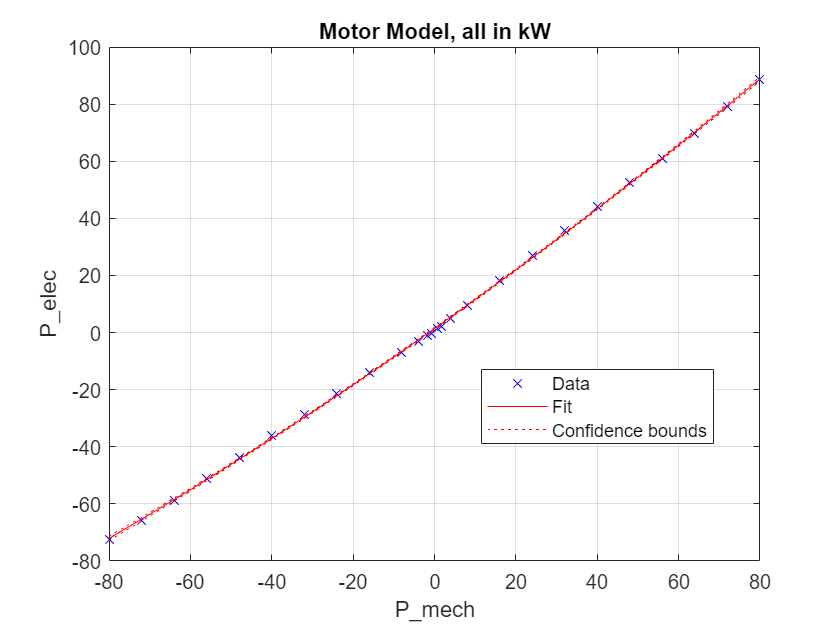

plot(mdl);
title('Motor Model, all in kW');
grid;

clear
% Vehicle Parameters
c = [0.397 0 130];
alpha = [1.8e-6 1 1400]';
m = 1633;

% Drive Cycle
%cycle = 20+10*sin((0:99)'/100*2*pi);
%cycle = abs(fft([randn(50,1);zeros(950,1)]))*3;
%cycle = [cycle.*0+1 cycle];
%cycle = elvio_cycle_eu_nedc();
cycle = elvio_cycle_cadc_urm150();
[v,t,a,a1,v0] = elvio_resample(cycle,0.1);
T = t(end);

P = polyval(c,v).*v + m.*v.*a;
Y = polyval(alpha,P);
Y0 = mean(Y)

Y0 = 8.9146e+03

Y0 * T

ans = 2.8036e+07

Y0 / v0 / 3.6

ans = 150.6774

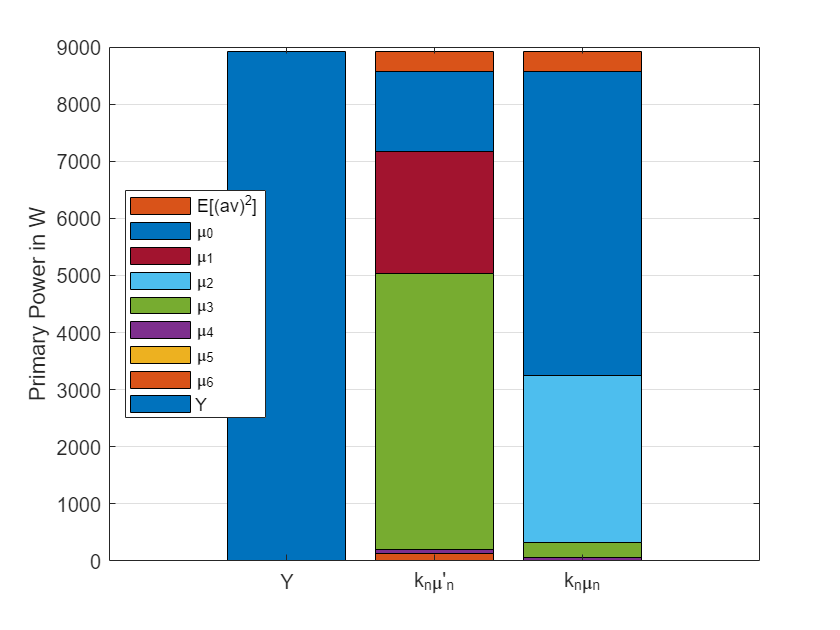


[kp,kp_av] = stat_kp(c,alpha,m);
[k,k_av] = stat_k(kp,kp_av,v0);

mup = [mean(v.^(6:-1:0)) mean((v.*a).^2)];
mu = [mean((v-v0).^(6:-1:0)) mean((v-v0).^(2:-1:0).*a.^2)];

Y1p = mup.*[kp(:)' kp_av(:)'];
Y1px = [[kp(:);kp_av(:)] mup' Y1p'];
Y2 = mu.*[k(:)' k_av(:)'];
Y2x = [[k(:);kp_av(:)] [mu(1:7)';mup(8)] [Y2(1:7)';Y1p(8)]];

Y012 = [Y0 zeros(1,8);0 Y1p;0 Y2(1:7) Y1p(8)];
h = bar(Y012,"stacked");
legend(flip(h), flip(["Y","\mu_6","\mu_5","\mu_4","\mu_3","\mu_2","\mu_1","\mu_0","E[(av)^2]"]),"Location","west");
ylabel("Primary Power in W");
set(gca,"xtick",1:3,"xticklabel",["Y","k_{n}\mu'_{n}","k_{n}\mu_{n}"]);
ylim([0 9000]);
grid;

out=sim('statsim');
